随机移动一个点，检查热阻，换热系数的变化

## 打开节点＆边文件

clc
clear

node_cor = load('F:\FEM\GraphAnalysis2\Optimiztion\symGraph\18_\nodes\df_Random_net_xy2607.txt');
bond_cor = load('F:\FEM\GraphAnalysis2\Optimiztion\symGraph\18_\edges\original_Network2607.txt');
% 调用函数路径
addpath('F:\FEM\GraphAnalysis2\Optimiztion\Function')

## 计算初始值

Tem_Initial = CalculateTemperatureForOpt(bond_cor,node_cor,0,12)

Tem_Initial =   119.1974  120.4393   54.7539   54.8681   78.7087    5.5617


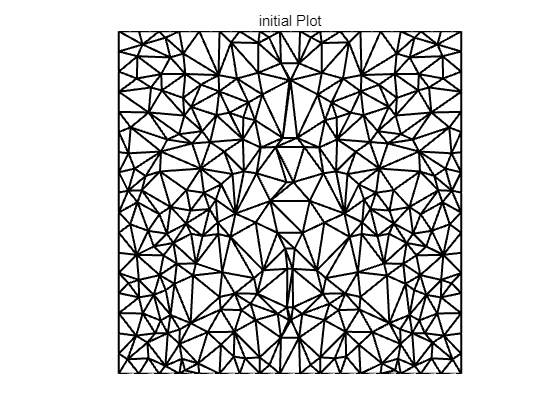

[S,A] = FunCalculateVolAre(bond_cor,node_cor);
h_avg = 20/(Tem_Initial(1,2)*(A*2*1e-9));

initial_Plot(bond_cor)

% 预存
Teminfo = zeros(200,7); %% 最后一行用来确定是何种方式跳出循环
Sizeinfo = zeros(200,2);
Hinfo = zeros(200,2);
random_move = zeros(200,2);


Teminfo(1,1:6) = Tem_Initial;
Sizeinfo(1,:) = [S,A];
Hinfo(1,1) = h_avg;
TemRecord = [];
h_avgRecord = [];

## 预存文件和基本信息

node_cor_opt = node_cor;
[n_r,n_c] = size(node_cor_opt);
maxiteration  =  30;
Sq = 5 %% 第Sq次移动

Sq = 5

## 进入循环

%%% 边界点最大序号 18*4-4 = 68

%%% 对称图形
%分离点坐标
SymP = (n_r-68)/2;

for i  = 1 :SymP

    % 初始化标志，表示是否找到使函数值减小的随机位移
    found_decreasing_move = false;
    TemRecord_temporary = []; % 临时温度表清空
    random_move_temporary = []; % 随机位移表清空
    h_avg_temporary = []; % 对流换热系数表清空

    iter = 0; %% 最大迭代次数归零
    while ~found_decreasing_move 
        node_cor_test = node_cor_opt;  %% 点位置归零

        %% 移动点保证对称
        random_vectorL = rand(1, 2)*((12/(18-1))/2);% 选择位移
        posL = i+68;
        node_cor_test(posL,:) = node_cor_test(posL,:) + random_vectorL;
        posR = 68+SymP+i;
        random_vectorR = [-random_vectorL(1,1) random_vectorL(1,2)];
        node_cor_test(posR,:) = node_cor_test(posR,:) + random_vectorR;

        % 德劳内三角化
        t = delaunayTriangulation(node_cor_test);
        % 坐标
        bond_cor_itr = edges(t);
        % 左边输进去
        bond_cor_itr(:,3) = node_cor_test(bond_cor_itr(:,1),1);
        bond_cor_itr(:,4) = node_cor_test(bond_cor_itr(:,1),2);
        bond_cor_itr(:,5) = node_cor_test(bond_cor_itr(:,2),1);
        bond_cor_itr(:,6) = node_cor_test(bond_cor_itr(:,2),2);

        %%计算
        Tem =  CalculateTemperatureForOpt(bond_cor_itr,node_cor_test,0,12);
        [S,A] = FunCalculateVolAre(bond_cor_itr,node_cor_test);
        h_avg = 20/(Tem(1,2)*(A*2*1e-9));
        h_avg_temporary = [h_avg_temporary; h_avg];
        TemRecord_temporary  = [TemRecord_temporary; Tem];
        random_move_temporary = [random_move_temporary;  random_vectorL];


        if h_avg >= Hinfo(i,1)
            % 当 Tem(1, 2) < Teminfo(i, 2) 时，直接跳出

            Hinfo(i+1, 2)  = 1; % 以第一种方式跳出循环
            
            found_decreasing_move = true;
            
        elseif iter >= maxiteration
            % 当 Tem(1, 2) 不小于 Teminfo(i, 2) 且 iter > maxiteration 时，找到最优

            min_value = min(h_avg(:, 1));

            % 使用逻辑索引找到第一个最小值所在的行数
            selected_row = find(h_avg(:, 1) == min_value, 1);

            % 提取相应数据到 random_vectorL_temporary
            random_vectorL_temporary = random_move_temporary(selected_row, :);

             %% 移动点保证对称
 
            node_cor_test(posL,:) = node_cor_test(posL,:) + random_vectorL_temporary;
            random_vectorR_temporary = [-random_vectorL_temporary(1,1) random_vectorL_temporary(1,2)];
            node_cor_test(posR,:) = node_cor_test(posR,:) + random_vectorR_temporary;

            % 保证使用这样的跳出方法也能记录随机量
            random_vectorL = random_vectorL_temporary;
            
            Hinfo(i+1, 2)  = 2;  % 以第二种方式跳出循环 

            % 跳出函数
            found_decreasing_move = true;
        end
        % 更新迭代次数
        iter = iter + 1;
        disp(iter)
        
    end
    %%记录   
    random_move(i+1,:) = random_vectorL;
    TemRecord = [TemRecord;TemRecord_temporary];
    h_avgRecord = [h_avgRecord;h_avg_temporary];
    node_cor_opt = node_cor_test; %% 点坐标更新
    Teminfo(i+1,1:6) = Tem; 
    Sizeinfo(i+1,:) = [S,A];
    Hinfo(i+1,1) = h_avg;
    disp(['第', num2str(i), '个点完成移动']);

end

     1



第1个点完成移动


     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17



第2个点完成移动


     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31



第3个点完成移动


     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31



第4个点完成移动


     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31



第5个点完成移动


     1



第6个点完成移动


     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31



第7个点完成移动


     1



第8个点完成移动


     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31



第9个点完成移动


     1



第10个点完成移动


     1



第11个点完成移动


     1



第12个点完成移动


     1



第13个点完成移动


     1



第14个点完成移动


     1



第15个点完成移动


     1



第16个点完成移动


     1

     2

     3

     4

     5

     6

     7



## 画图

% 生成x坐标
y = 1:SymP
x = y'
initial_Plot(bond_cor_itr)

plot(x',Teminfo(1:SymP,2))
title('热阻')
figure
plot(x',Sizeinfo(1:SymP,2))
title('体积')
figure
plot(x',Hinfo(1:SymP ,1))
title('平均对流换热系数')

## 保存文件

writematrix(Hinfo,['F:\FEM\GraphAnalysis2\Optimiztion\Movepoint\iter',num2str(maxiteration),'\','Hinfo',num2str(maxiteration),'_',num2str(Sq),'.txt'],Delimiter= ' ');
writematrix(Sizeinfo,['F:\FEM\GraphAnalysis2\Optimiztion\Movepoint\iter',num2str(maxiteration),'\','Size',num2str(maxiteration),'_',num2str(Sq),'.txt'],Delimiter= ' ');
writematrix(Teminfo,['F:\FEM\GraphAnalysis2\Optimiztion\Movepoint\iter',num2str(maxiteration),'\','Tem',num2str(maxiteration),'_',num2str(Sq),'.txt'],Delimiter= ' ');
writematrix(random_move,['F:\FEM\GraphAnalysis2\Optimiztion\Movepoint\iter',num2str(maxiteration),'\','random_move',num2str(maxiteration),'_',num2str(Sq),'.txt'],Delimiter= ' ');